close all
clear
clc

## set parameters

current stock price

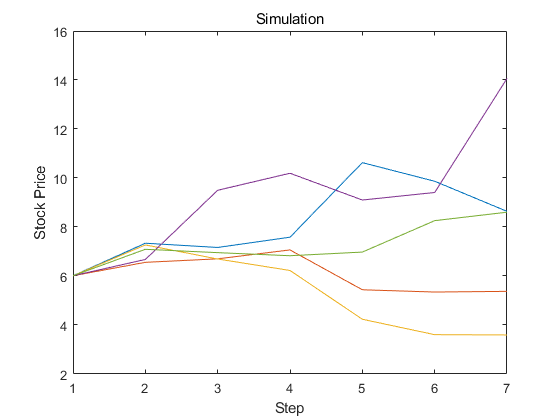

S0 = 6.01;
% strike price
K = 6.24;
% risk-free rate
r = 0.02683;
% time to maturity
T = 1;
% stock volatility
sigma = 0.3386;
% time steps
nStep = 6;
% path
nPath = 5;
% simulate stock price
PricePath = sPath(S0,r,sigma,T,nStep,nPath);
% plot
figure
for i = 1:nPath
    plot(1:length(PricePath(i,:)),PricePath(i,:))
    hold on;
end
hold off;
title('Simulation');
xlabel('Step')
ylabel('Stock Price')

## American call Option

% C = LSM(r,K,T,PricePath);